%% Bode Method
[kp, ki, kd] = BodMet(10*pi,60,simp_model);
kp

kp = 7.5244

ki

ki = 94.0379

kd

kd = 0.1505

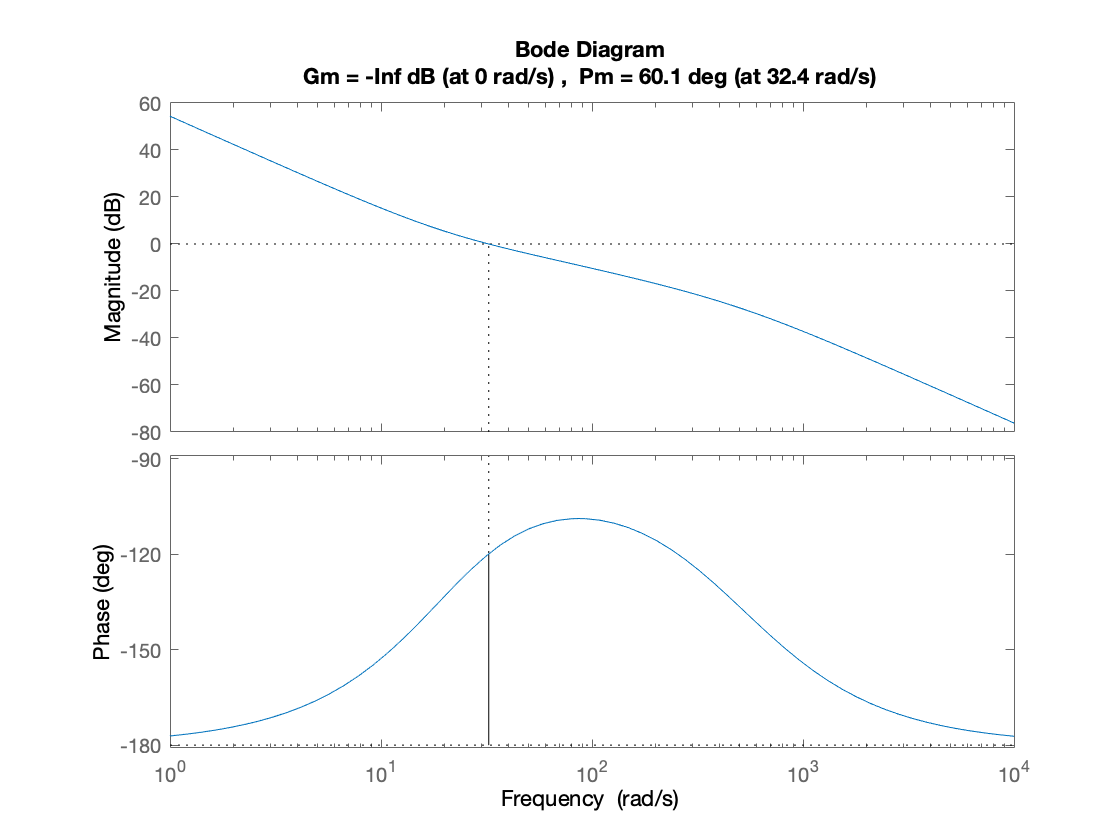

s = tf('s');
bod_met.controller = kp + ki/s + kd*s/(0.002*s+1);
margin(bod_met.controller*simp_model.P)

bod_met.W = feedback(bod_met.controller * simp_model.P,1); % Closed loop t.f.
bod_met.W

ans =
 
                12.89 s^2 + 600.5 s + 7322
  -------------------------------------------------------
  0.0008307 s^4 + 0.4434 s^3 + 26.89 s^2 + 600.5 s + 7322
 
Continuous-time transfer function.



simp_model.P

ans =
 
        77.86
  -----------------
  0.4154 s^2 + 14 s
 
Continuous-time transfer function.



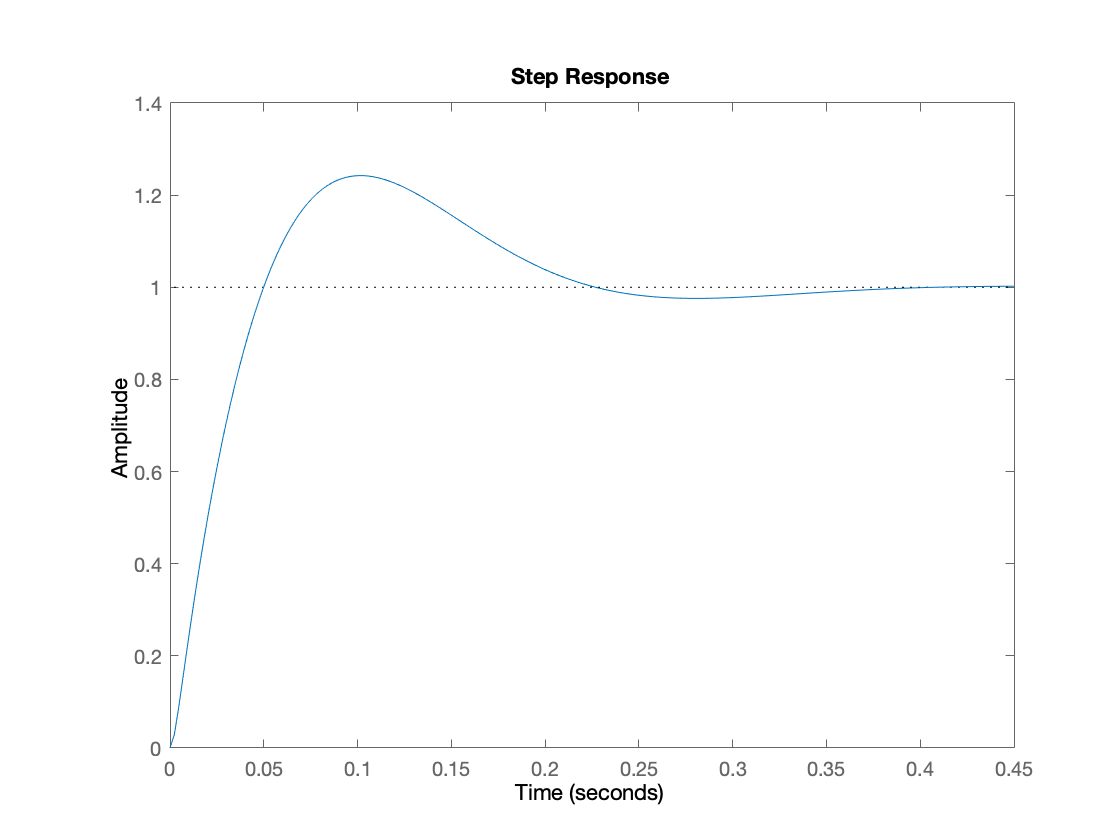

charac.tr = stepinfo(bod_met.W).RiseTime;
charac.ts = stepinfo(bod_met.W).SettlingTime;
charac.mp = stepinfo(bod_met.W).Overshoot;

step(bod_met.W)

charac

charac = struct with fields:
    tr: 0.0369
    ts: 0.3117
    mp: 24.2410



kp

kp = 7.5244

ki

ki = 94.0379

kd

kd = 0.1505

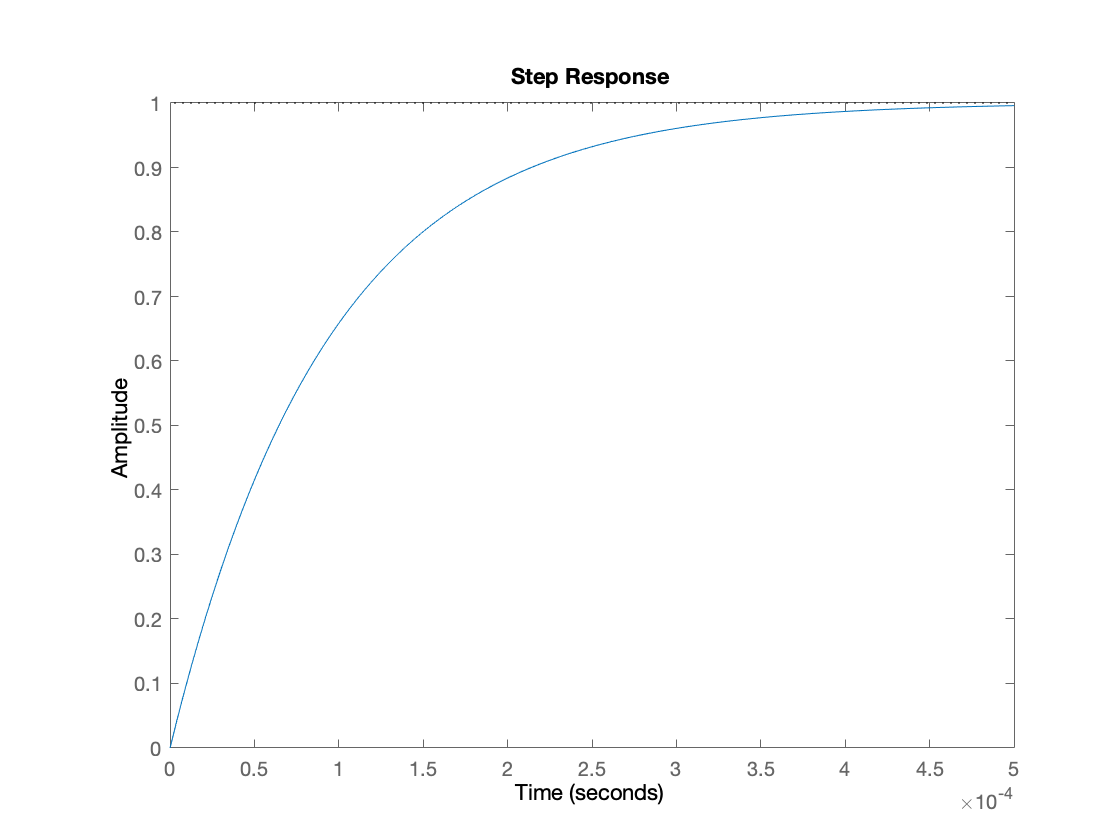


%% best Kp, Ki, Kd
deltaKp = 4; 
deltaKi = 20; 
deltaKd = 1; 
K_p = 40:deltaKp:60;
K_i = 80:deltaKi:180;
K_d = 1:deltaKd:10;
kp_best = kp;
ki_best = ki;
kd_best = kd;
tss = charac.ts;
trr = charac.tr;
mpp = charac.mp;
for KP=K_p
    for KI=K_i
        for KD=K_d
           s = tf('s');
           C = KP+KI/s+KD*s/(0*s+1);
           W = feedback(C*simp_model.P*rad2deg,1);
           if (stepinfo(W).SettlingTime < tss && stepinfo(W).Overshoot < mpp)
                 tss = stepinfo(W).SettlingTime;
                 mpp = stepinfo(W).Overshoot;
                 kp_best = KP;
                 ki_best = KI;
                 kd_best = KD;
           end
        end
    end
end
bod_met.best_controller = kp_best+ki_best/s+kd_best*s/(0*s+1);
bod_met.best_W = feedback(bod_met.best_controller * simp_model.P*rad2deg,1);
figure(2);
step(bod_met.best_W)

kp

kp = 7.5244

ki

ki = 94.0379

kd

kd = 0.1505

kp_best = 60

kp_best = 60

ki_best = 100

ki_best = 100

kd_best = 1

kd_best = 1

%% Function definition

function [kp, ki, kd] = BodMet(w_gc,ph_m,simp_model)
%d = log(1/Mp) / sqrt(pi^2 + log(1/Mp)^2);   %   damping factor
%d
%w_gc = 3/(d*ts);    %   gain crossover freq [rad/s]      
%w_gc
%ph_m = 180/pi * atan(2*d/sqrt(sqrt(1+4*d^4)-2*d^2));
%ph_m
[mag_wgc, phm_wgc] = bode(simp_model.P,w_gc); % gain,phase of P(iw_gc)
deltaK = 1/mag_wgc; % DeltaK
deltaPhi = -180 + ph_m - phm_wgc; % DeltaPhi
kp = deltaK * cosd(deltaPhi); % K_p
T_d = (tand(deltaPhi) + sqrt(tand(deltaPhi)^2 + 1))/(2*w_gc); % T_d
T_i = 4*T_d; % T_i
ki = kp/T_i; % K_i
kd = kp*T_d; % K_d
end